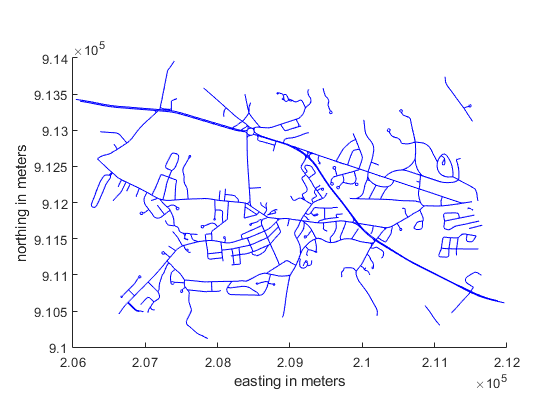

%% Creating Maps Using MAPSHOW
% This example shows how to create a range of different maps using
% |mapshow|.

% Copyright 2003-2015 The MathWorks, Inc.

%% Map 1: Concord Roads - A Geographic Data Structure
% Display a geographic data structure array with lines representing
% roads. In the shapefile 'concord_roads.shp', the road coordinates have
% been pre-projected to the Massachusetts Mainland State Plane system
% (in meters), so the shapefile is imported into a mapstruct (the
% variable 'roads').
roads = shaperead('concord_roads.shp');
figure
mapshow(roads);
xlabel('easting in meters')
ylabel('northing in meters')

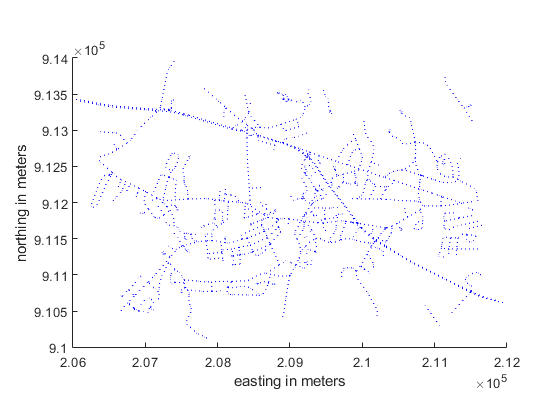


%% Map 2: Concord Roads with Custom LineStyle
% Display the roads shape and change the LineStyle.
figure
mapshow('concord_roads.shp','LineStyle',':');
xlabel('easting in meters')
ylabel('northing in meters')


%% Map 3: Concord Roads with SymbolSpec 
% Display the roads shape, and render using a SymbolSpec.

%% 
% To learn about the |concord_roads.shp| dataset, read its associated
% |concord_roads.txt| metadata file which describes the attributes.
type concord_roads.txt


  A shapefile data set for roads in part of Concord, Massachusetts,
  USA comprising the following files:
 
     concord_roads.dbf
     concord_roads.shp
     concord_roads.shx
 
  Source
  ------
  Office of Geographic and Environmental Information (MassGIS),
  Commonwealth of Massachusetts  Executive Office of Environmental Affairs
  (http://www.state.ma.us/mgis/)
 
  Coordinate system/projection
  ----------------------------
  All data distributed by MassGIS are registered to the NAD83 datum,
  Massachusetts State Plane Mainland Zone coordinate system. Units are in
  meters.
 
  Data set construction
  ---------------------
  This data set was constructed by concatenating Massachusetts Highway
  Department road shapefiles for the Maynard and Concord USGS Quadrangles,
  from compressed files mrd97.exe and mrd104.exe.
 
  Features were selected with bounding boxes intersecting the following
  box:
            [206500 (min easting)  910500 (min northing)
             211500 (max east


%%
% Query the attributes in this roads file.
roads = shaperead('concord_roads.shp')

roads = 609×1 struct array with fields:
    Geometry
    BoundingBox
    X
    Y
    STREETNAME
    RT_NUMBER
    CLASS
    ADMIN_TYPE
    LENGTH



%%
% Find out how many roads fall in each CLASS.
histcounts([roads.CLASS],'BinLimits',[1 7],'BinMethod','integer')

ans =      0    14    93    26   395    81     0



%%
% Find out how many roads fall in each ADMIN_TYPE.
histcounts([roads.ADMIN_TYPE],'BinLimits',[0 3],'BinMethod','integer')

ans =    502     0     0   107


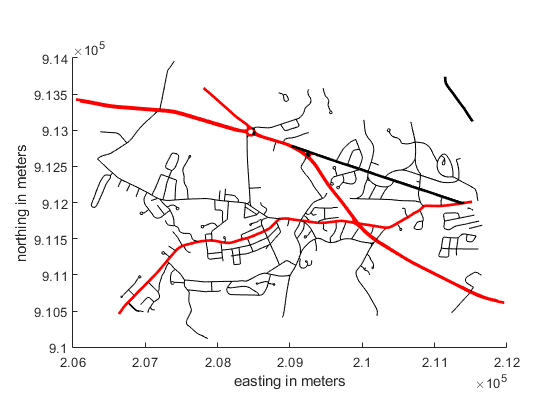


%%
% Notice that there are no roads in this file that are CLASS 1 or 7, and
% the roads are either ADMIN_TYPE 0 or 3.
%
% Create a SymbolSpec to: 
%
% * Color local roads (ADMIN_TYPE=0) black. 
% * Color state roads (ADMIN_TYPE=3) red.
% * Hide very minor roads (CLASS=6).
% * Set major or larger roads (CLASS=1-4) with a LineWidth of 2.0.
roadspec = makesymbolspec('Line',...
    {'ADMIN_TYPE',0, 'Color','black'}, ...
    {'ADMIN_TYPE',3, 'Color','red'},...
    {'CLASS',6, 'Visible','off'},...
    {'CLASS',[1 4], 'LineWidth',2});
figure
mapshow('concord_roads.shp','SymbolSpec',roadspec);
xlabel('easting in meters')
ylabel('northing in meters')

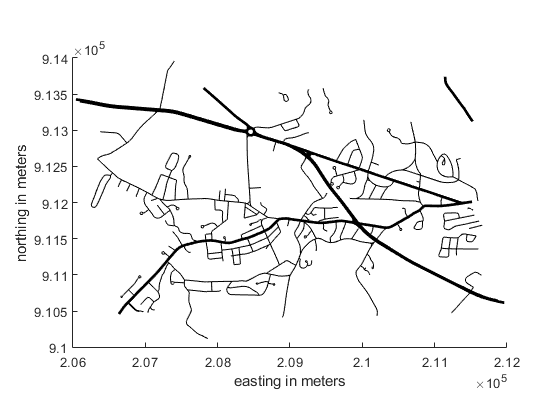


%% Map 4: Concord Roads, Override SymbolSpec 
% Override a graphics property of the SymbolSpec.
roadspec = makesymbolspec('Line',...
    {'ADMIN_TYPE',0, 'Color','black'}, ...
    {'ADMIN_TYPE',3, 'Color','red'},...
    {'CLASS',6, 'Visible','off'},...
    {'CLASS',[1 4], 'LineWidth',2});
figure
mapshow('concord_roads.shp','SymbolSpec',roadspec,'Color','black');
xlabel('easting in meters')
ylabel('northing in meters')

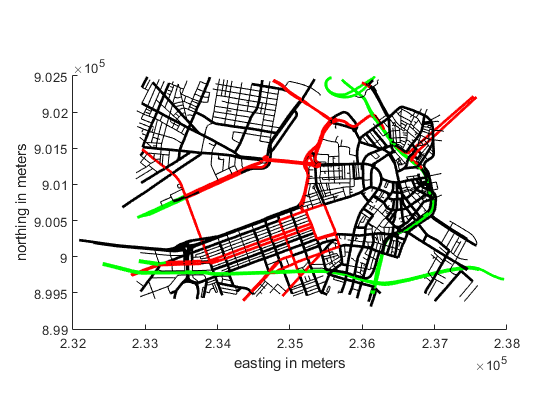

 
%% Map 5: Boston Roads with SymbolSpec, Override Defaults
% Override default property of the SymbolSpec.
roadspec = makesymbolspec('Line',...
    {'Default', 'Color','green'}, ...
    {'ADMIN_TYPE',0, 'Color','black'}, ...
    {'ADMIN_TYPE',3, 'Color','red'},...
    {'CLASS',6, 'Visible','off'},...
    {'CLASS',[1 4], 'LineWidth',2});
figure
mapshow('boston_roads.shp','SymbolSpec',roadspec);
xlabel('easting in meters')
ylabel('northing in meters')

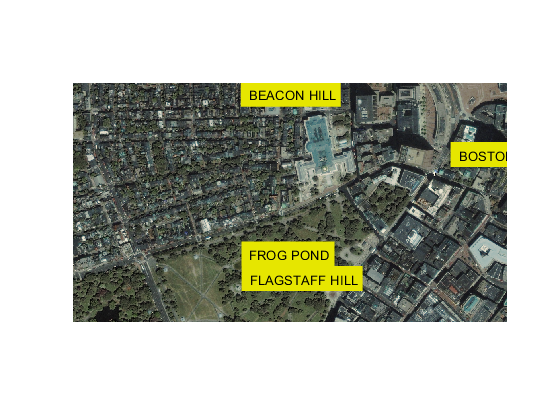


%% Map 6: GeoTIFF Image of Boston
% Display the Boston GeoTIFF image; includes material (c) GeoEye(TM), all
% rights reserved.
figure
mapshow boston.tif
axis image manual off

%%
% Read Boston placenames in order to overlay on top of the GeoTIFF image.
S = shaperead('boston_placenames.shp');

%%
% The projection in the GeoTIFF file is in units of survey feet. The point
% coordinates in the shapefile are in meters. Therefore, we need to convert
% the placename coordinates from meters to survey feet in order to overlay
% the points on the image.
surveyFeetPerMeter = unitsratio('sf', 'meter');
for k = 1:numel(S)
    S(k).X = surveyFeetPerMeter * S(k).X;
    S(k).Y = surveyFeetPerMeter * S(k).Y;
end

%% 
% Display the placenames.
text([S.X], [S.Y], {S.NAME}, 'Color', [0 0 0], ...
    'BackgroundColor',[0.9 0.9 0],'Clipping','on');

%%
% Zoom in on a selected region.
xlim([ 772007,  775582])
ylim([2954572, 2956535])

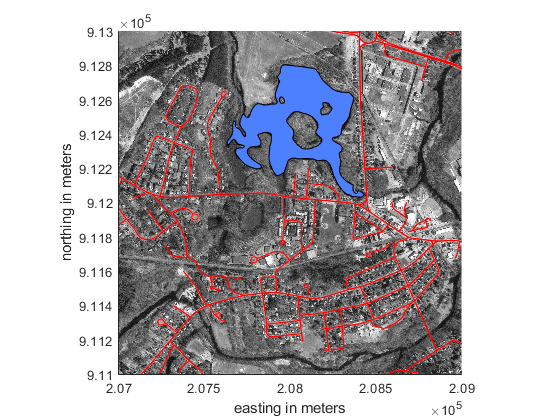


%% Map 7: Pond with Islands over Orthophoto Backdrop
% Display a pond with three large islands (feature 14 in the
% concord_hydro_area shapefile).  Note that islands are visible in the
% orthophoto through three "holes" in the pond polygon. Display roads in
% the same figure.
[ortho, cmap] = imread('concord_ortho_w.tif');
R = worldfileread('concord_ortho_w.tfw', 'planar', size(ortho));
figure
mapshow(ortho, cmap, R)

%%
% Save map limits used for image
xLimits = xlim;
yLimits = ylim;
pond = shaperead('concord_hydro_area.shp', 'RecordNumbers', 14);
hold on
mapshow(pond, 'FaceColor', [0.3 0.5 1], 'EdgeColor', 'black')
mapshow('concord_roads.shp', 'Color', 'red', 'LineWidth', 1);
xlabel('easting in meters')
ylabel('northing in meters')

%%
% Restore map limits to match image
xlim(xLimits)
ylim(yLimits)

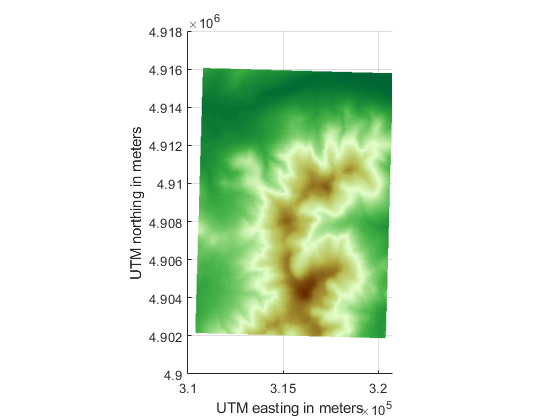


%% Map 8: Mount Washington SDTS Digital Elevation Model

%%
% View the Mount Washington terrain data as a mesh. The data grid is
% georeferenced to Universal Transverse Mercator (UTM) zone 19.
figure
h = mapshow('9129CATD.ddf','DisplayType','mesh');
Z = h.ZData;
demcmap(Z)
xlabel('UTM easting in meters')
ylabel('UTM northing in meters')

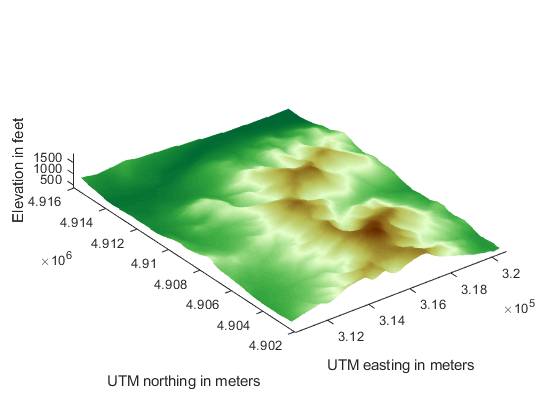


%%
% View the Mount Washington terrain data as a 3-D surface. Use the default
% 3-D view, which shows how the range looks from the southwest.
figure
mapshow('9129CATD.ddf');
demcmap(Z)
view(3); 
axis equal;
xlabel('UTM easting in meters')
ylabel('UTM northing in meters')
zlabel('Elevation in feet')

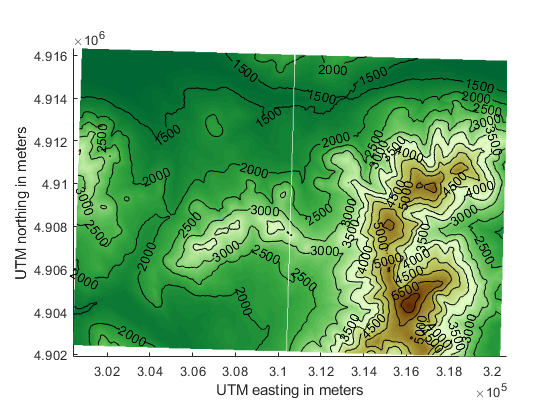


%% Map 9: Mount Washington and Mount Dartmouth on One Map with Contours
% Display the grid and contour lines of Mount Washington and Mount
% Dartmouth.

%%
% Read the terrain data files.
[Z_W, R_W] = arcgridread('MtWashington-ft.grd');
[Z_D, R_D] = arcgridread('MountDartmouth-ft.grd');

%%
% Display the terrain data as a surface in the z == 0 plane,
% so that overlying contour lines and labels will be visible.
figure
hold on
mapshow(zeros(size(Z_W)),R_W,'CData',Z_W,'DisplayType','surface')
mapshow(zeros(size(Z_D)),R_D,'CData',Z_D,'DisplayType','surface')
demcmap(Z_W)
xlabel('UTM easting in meters')
ylabel('UTM northing in meters')
axis equal

%%
% Overlay black contour lines and labels.
cW = mapshow(Z_W, R_W, 'DisplayType', 'contour', ...
   'LineColor', 'black', 'ShowText', 'on');
cD = mapshow(Z_D, R_D, 'DisplayType', 'contour', ...
   'LineColor', 'black', 'ShowText', 'on');


%% Credits
% boston_roads.shp, concord_roads.shp, concord_hydro_line.shp,
% concord_hydro_area.shp, concord_ortho_e.tif:
%
%    Office of Geographic and Environmental Information (MassGIS),
%    Commonwealth of Massachusetts Executive Office of Environmental Affairs
%    http://www.state.ma.us/mgis
%
% boston.tif
%
%    Copyright GeoEye 
%    Includes material copyrighted by GeoEye, all rights reserved.      
%    (GeoEye was merged into the DigitalGlobe corporation January 29th,
%    2013.)
%
%    For more information, run: 
%    
%    >> type boston.txt
%
% 9129CATD.ddf (and supporting files): 
% 
%    United States Geological Survey (USGS) 7.5-minute Digital Elevation
%    Model (DEM) in Spatial Data Transfer Standard (SDTS) format for the
%    Mt. Washington quadrangle, with elevation in meters.
%    http://edc.usgs.gov/products/elevation/dem.html
%
%    For more information, run: 
%    
%    >> type 9129.txt
%
% MtWashington-ft.grd, MountDartmouth-ft.grd:
%
%    MtWashington-ft.grd is the same DEM as 9129CATD.ddf, but converted to
%    Arc ASCII Grid format with elevation in feet.
%
%    MountDartmouth-ft.grd is an adjacent DEM, also converted to Arc ASCII
%    Grid with elevation in feet.
%
%    For more information, run: 
%    
%    >> type MtWashington-ft.txt
%    >> type MountDartmouth-ft.txt
%
